## Step 1: Load Image

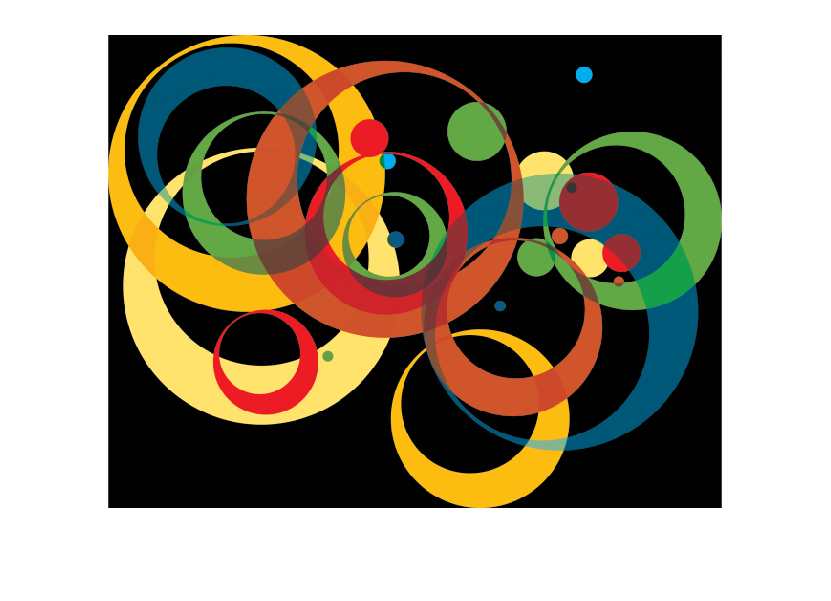

rgb = imread('cercles.png');
figure
imshow(rgb)

## Step 2: Determine Radius Range for Searching Circles

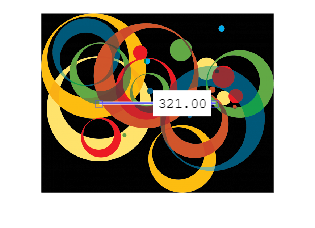

d = imdistline;

%delete(d);

## Step 3: Initial Attempt to Find Circles

RADIUS_RANGE=[5 160];
[centers, radii] = imfindcircles(rgb,RADIUS_RANGE);

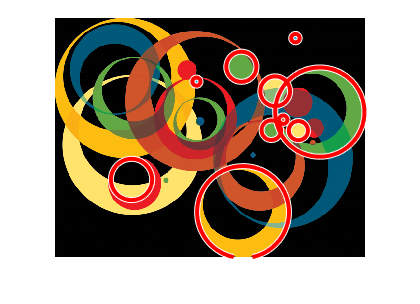

h=viscircles(centers,radii);

## Step 4: Increase Detection Sensitivity

clear centers radii h
[centers, radii] = imfindcircles(rgb,RADIUS_RANGE,'Sensitivity',0.9)

centers =   386.4884  101.4744
  498.4012   42.0791
  504.7480  234.1397
  448.3908  232.6534
  473.2888  211.0010
  456.8493  152.7106
  390.1866  402.3230
  158.5505  334.9980
  293.4253  132.4661
  548.4425  195.9047


radii =    31.2077
    8.6485
   19.7833
   20.0308
    8.6990
   30.8476
   95.1354
   42.6871
    8.3652
   91.6860


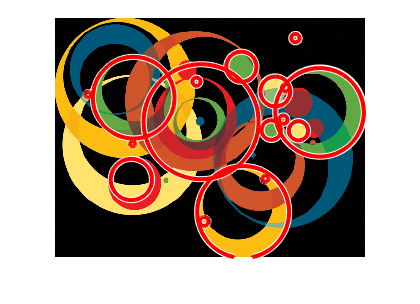

h=viscircles(centers,radii);

%'ObjectPolarity','dark'


## Step 4.1: Increase Detection Sensitivity

clear centers radii h
[centers, radii] = imfindcircles(rgb,RADIUS_RANGE,'Sensitivity',0.95)

centers =   386.7372  101.2307
  498.2907   42.0846
  504.9335  234.0057
  448.4488  232.9601
  473.3731  211.0000
  456.9279  152.5046
  390.1572  402.1740
  158.8942  334.8305
  293.2752  132.2786
  548.6317  196.0076


radii =    31.1847
    8.6485
   19.7833
   20.0308
    8.6990
   30.8476
   95.1354
   42.6871
    8.3652
   91.4467


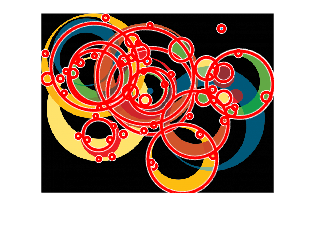

h=viscircles(centers,radii);

%'ObjectPolarity','dark'

## Step 4.2: Increase Detection Sensitivity

clear centers radii h
[centers, radii] = imfindcircles(rgb,RADIUS_RANGE,'Sensitivity',0.99)

centers =   386.4914  101.4801
  498.0000   42.3555
  504.5664  234.0000
  448.0000  233.0000
  473.0000  211.0000
  457.0000  153.0000
  390.4681  402.4943
  159.1885  334.5834
  293.3719  132.4960
  548.5246  196.0260


radii =    31.2077
    8.6485
   19.7833
   20.0308
    8.6990
   30.8476
   95.1354
   42.6871
    8.3652
   91.4467


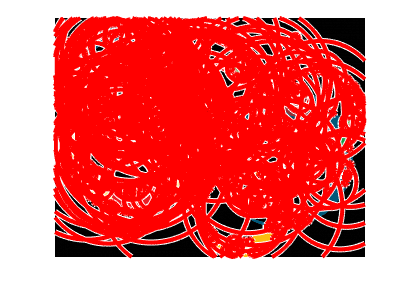

viscircles(centers,radii);

%'ObjectPolarity','dark'

## Step 6: Use the Second Method (Two-stage) for Finding Circles

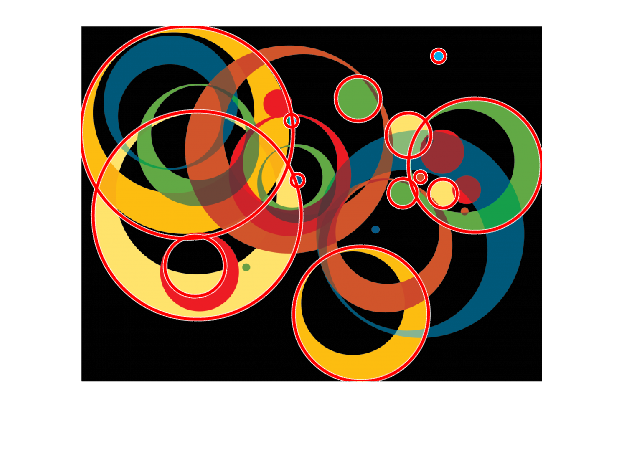

clear centers radii h
[centers, radii] = imfindcircles(rgb,RADIUS_RANGE,'Method','twostage');

## Step 7: Why are Some Circles Still Getting Missed?

Looking at the last result, it is curious that |imfindcircles| does not find the yellow chips in the image. The yellow chips do not have strong contrast with the background. In fact they seem to have very similar intensities as the background. Is it possible that the yellow chips are not really 'darker' than the background as was assumed? To confirm, show the grayscale version of this image again.

figure,
imshow(gray_image);

## Step 8: Find 'Bright' Circles in the Image

The yellow chips are almost the same intensity, maybe even brighter, as compared to the background. Therefore, to detect the yellow chips, change 'ObjectPolarity' to 'bright'.

[centersBright, radiiBright] = imfindcircles(rgb,RADIUS_RANGE,'ObjectPolarity','bright','Sensitivity',0.9);

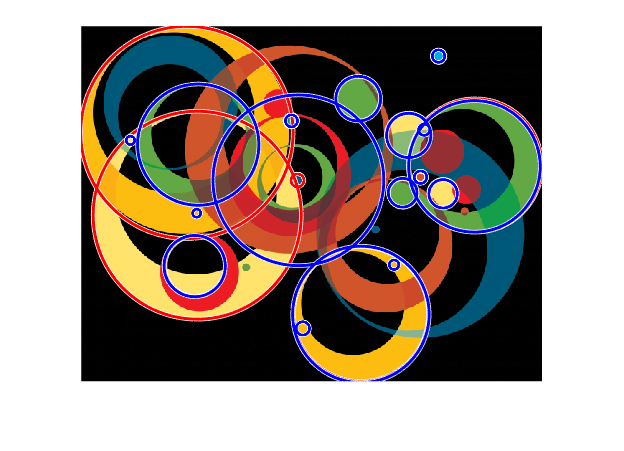

hBright = viscircles(centersBright, radiiBright,'Color','b');

## Step 9: Draw 'Bright' Circles with Different Color

Draw the _bright_ circles in a different color, by changing the 'Color' parameter in |viscircles|.

figure,
imshow(rgb); 

hBright = viscircles(centersBright, radiiBright,'Color','b');

%%

Note that three of the missing yellow chips were found, but one yellow chip is still missing.  These yellow chips are hard to find because  they don't _stand out_ as well as others on this background.

## Step 10: Lower the Value of 'EdgeThreshold' 

[centersBright, radiiBright, metricBright] = imfindcircles(rgb,RADIUS_RANGE,'ObjectPolarity','bright','Sensitivity',0.92,'EdgeThreshold',0.5);

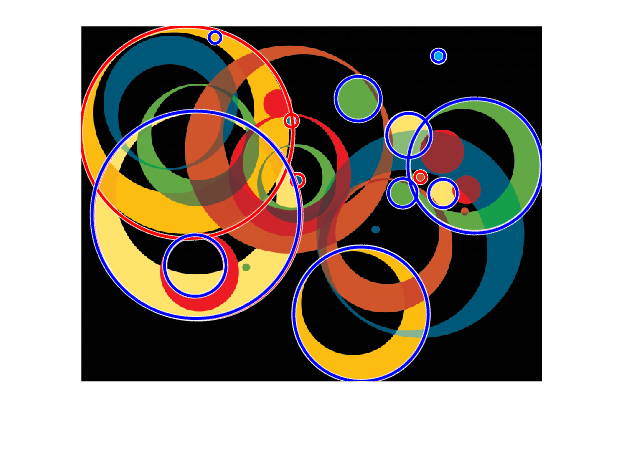


delete(hBright);

hBright = viscircles(centersBright, radiiBright,'Color','b');

## Step 11: Draw 'Dark' and 'Bright' Circles Together

clear hBright h hDark

[centersBright, radiiBright, metricBright] = imfindcircles(rgb,RADIUS_RANGE,'ObjectPolarity','bright','Sensitivity',0.9,'EdgeThreshold',0.4);

[centersDark, radiiDark, metricDark] = imfindcircles(rgb,RADIUS_RANGE,'ObjectPolarity','dark','Sensitivity',0.85,'EdgeThreshold',0.4);

[centers, radii] = imfindcircles(rgb,RADIUS_RANGE,'Method','twostage');

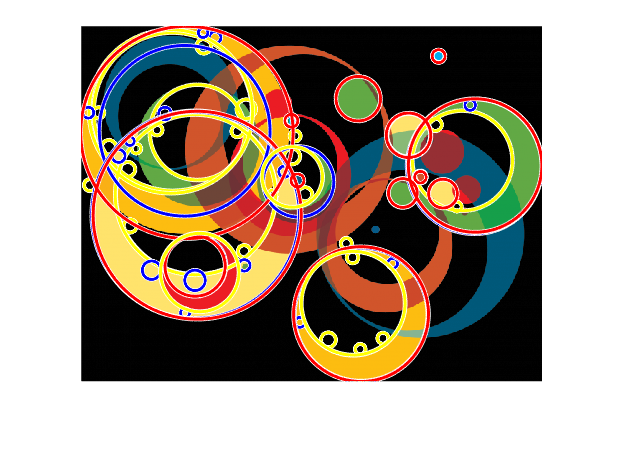


hBright = viscircles(centersBright, radiiBright,'Color','b');
h = viscircles(centers,radii);
hDark = viscircles(centersDark, radiiDark,'Color','y');